# Basic Gradient Descent algorithm

## Example 1

Function to minimize using gradient descent: $f(x, y) = x^2 + y^2$

f = @(V)(V(1)^2 + V(2)^2);

The gradient : $\nabla f(x, y) = \left[\frac{\partial f}{\partial x} ;\; \frac{\partial f}{\partial y}\right] = 
\left[2x ;\; 2y\right]$

g = @(V)([2*V(1); 2*V(2)]/sqrt((2*V(1))^2 + (2*V(2))^2));
x = -10:0.5:10;
[X, Y] = meshgrid(x, x);
Z = X.^2 + Y.^2;
figure,
surf(x, x, Z); view([-27 67])
xlabel('x'), ylabel('y'), zlabel('z');
title('Function to minimize $f(x, y) = x^2 + y^2$', 'Interpreter', 'latex'); 

Initialization

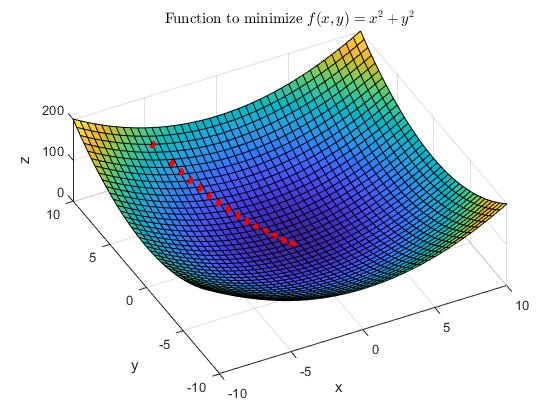

stepSize = 0.7;
V = [-5; 9];
min = f(V);
hold on;
plot3(V(1), V(2), f(V), 'Color', 'Red', "MarkerSize",20, "Marker",".");

V = V - stepSize*g(V);
while f(V) < min
    min = f(V);
    V = V - stepSize*g(V);
    plot3(V(1), V(2), f(V), 'Color', 'Red', "MarkerSize",20, "Marker",".");
end

## Linear regression

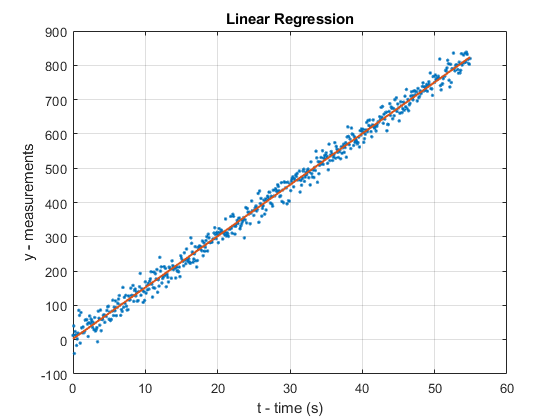

n = 550;
t = 0:0.1:(0.1*n-0.1);
y = 15*t + 2;
y = y + normrnd(0, 20, [1, length(y)]);
figure, 
plot(t, y, '.'), grid;
xlabel('t - time (s)');
ylabel('y - measurements');
title('Linear Regression')

A = [sum(t.^2) sum(t); 
     sum(t) length(t)];
B = [sum(y.*t) sum(y)];
sol = B/A;
y_hat = sol(1)*t + sol(2);
hold on;
plot(t, y_hat, "LineWidth", 1.5);

## Regression using gradient descent

Model: $\hat{y} = ax + b
$


$$J(a, b) = \sum_{k = 1}^{n}(y(k) - \hat{y}(k))^2\\
\nabla J(a, b) = \left[\frac{\partial J}{\partial a}; \frac{\partial J}{\partial b}\right] = 
\left[ 
-2 \sum_{k = 1}^n \left[ x(k)(y(k) - ax(k) - b) \right]\;;
-2 \sum_{k = 1}^n \left[y(k) - ax(k) - b \right] 
\right]\\
\left[
\matrix{a_{n + 1} \cr b_{n + 1}} 
\right]
 = 
\left[
\matrix{a_n \cr b_n} 
\right]
 - \alpha \frac{\nabla J(a_n, b_n)}{||\nabla J(a_n, b_n)||}}$$


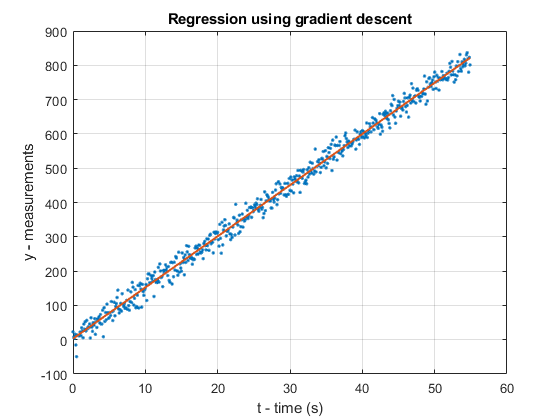

n = 550;
t = 0:0.1:(0.1*n-0.1);
y = 15*t + 2;
y = y + normrnd(0, 20, [1, length(y)]);

gradient = zeros(2, length(y));
theta = zeros(2, length(y));
gradient(:, 1) = [-2*t(1)*(y(1) - theta(1, 1)*t(1) - theta(2, 1));
                  -2*(y(1) - theta(1, 1)*t(1) - theta(2, 1))];
gradient(:, 1) = gradient(:, 1)/sqrt(gradient(1, 1)^2 + gradient(2, 1)^2);
stepSize = 0.1;
cost = zeros(1, length(y));
cost_handler = @(y, y_hat)(norm(y - y_hat)/norm(y - mean(y)));
cost(1) = cost_handler(y(1), theta(1, 1)*t(1) + theta(2, 1));

for i = 2:length(y)
    theta(:, i) = theta(:, i - 1) - stepSize*gradient(:, i - 1);
    gradient(:, i) = gradient(:, i - 1) + [-2*t(i)*(y(i) - theta(1, i)*t(i) - theta(2, i));
                                           -2*(y(i) - theta(1, i)*t(i) - theta(2, i))]; 
    gradient(:, i) = gradient(:, i)/sqrt(gradient(1, i)^2 + gradient(2, i)^2);
    cost(i) = cost_handler(y(1:i), theta(1, 1:i).*t(1:i) + theta(2, 1:i));
end

y_hat = theta(1, end)*t + theta(2, end);
figure, 
plot(t, y, '.'), grid; hold on;
plot(t, y_hat, "LineWidth", 1.5);
xlabel('t - time (s)');
ylabel('y - measurements');
title('Regression using gradient descent');

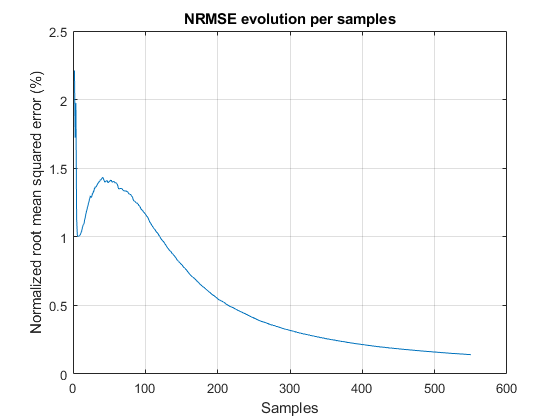


figure, 
plot(cost);
xlabel('Samples'); ylabel('Normalized root mean squared error (%)');
title('NRMSE evolution per samples')
grid;

## First order system identification using gradient descent


$$\frac{Y(Z^{-1})}{U(Z^{-1})} = \frac{az^{-1}}{1 + bz^{-1}}\\
y[n] = au[n - 1] - by[n - 1]\\
e[n] = y[n] - \hat{y}[n]\\
J(a, b) = \sum_{k = 1}^{N}e[k]^2 = \sum_{k = 1}^{N}(y[k] - \hat{y}[k])^2 = \sum_{k = 1}^{N}(y[k] - au[k - 1] + by[k - 1])^2\\
\frac{\partial J}{\partial a} = -2\sum_{k = 1}^{N} \left[ (y[k] - au[k - 1] + by[k - 1])u[n - 1]\right]\\
\frac{\partial J}{\partial b} = 2\sum_{k = 1}^{N} \left[ (y[k] - au[k - 1] + by[k - 1])y[n - 1]\right]\\
\left[
\matrix{a_{n + 1} \cr b_{n + 1}} 
\right]
 = 
\left[
\matrix{a_n \cr b_n} 
\right]
 - \alpha \frac{\nabla J(a_n, b_n)}{||\nabla J(a_n, b_n)||}}
$$


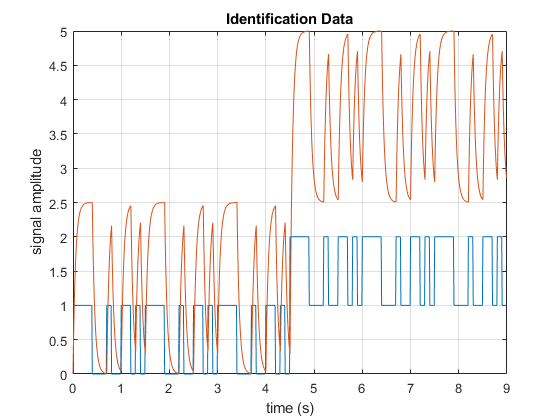

H = tf(5, [0.1 2]);
Te = 0.01;
Hd = c2d(H, Te, 'zoh');

[u, t] = SPAB_GEN(4, 3, 4, Te, 10, 6);
u(451:end) = 1 + u(451:end);
[num, den] = tfdata(Hd, 'v');
y = dlsim(num, den, u);

figure, 
plot(t, [u' y]); grid;
xlabel('time (s)'), ylabel('signal amplitude');
title('Identification Data');

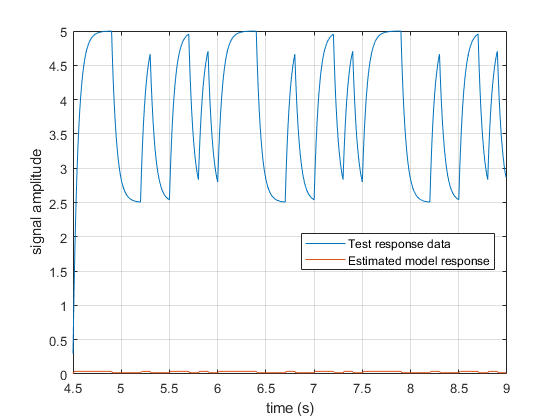


uTrain = u(1:450);
yTrain = y(1:450);
uTest = u(451:end);
yTest = y(451:end);
tTest = t(451:end);

theta = zeros(2, length(uTrain));
gradient = zeros(2, length(uTrain));
stepSize = 0.001;

for i = 2:length(uTrain)
    theta(:, i) = theta(:, i - 1) - stepSize*gradient(:, i - 1);
    gradient(:, i) = gradient(:, i - 1) + [(-2)*(yTrain(i) - theta(1, i)*uTrain(i - 1) ...
                                           + theta(2, i)*yTrain(i - 1))*uTrain(i - 1);
                                           (2)*(yTrain(i) - theta(1, i)*uTrain(i - 1) ...
                                           + theta(2, i)*yTrain(i - 1))*yTrain(i - 1)];
    gradient(:, i) = gradient(:, i)/sqrt(gradient(1, i)^2 + gradient(2, i)^2);
end

H_hat = tf(theta(1, 50), [1 theta(2, 50)], Te);
[num, den] = tfdata(H_hat, 'v');
y_hat = dlsim(num, den, uTest);

figure,
plot(tTest, [yTest y_hat]); grid;
xlabel('time (s)'), ylabel('signal amplitude');
legend('Test response data', 'Estimated model response');
legend('Location',"best")

function [spab, t] = SPAB_GEN(N, i, j, Te, alpha, numberOfPeriods)
    register = ones(1, N*numberOfPeriods);
    spab = zeros(1, (2^N - 1)*alpha*numberOfPeriods);
    t = 0:Te:((2^N - 1)*alpha*Te)*numberOfPeriods - Te;
    m = 1;
    
    for k = 1:(2^N - 1)*numberOfPeriods
        spab(m:m + alpha - 1) = register(end)*ones(1, alpha);
        m = m + alpha;
        aux = xor(register(i), register(j));
        register = [aux register(1:N - 1)];
    end
end